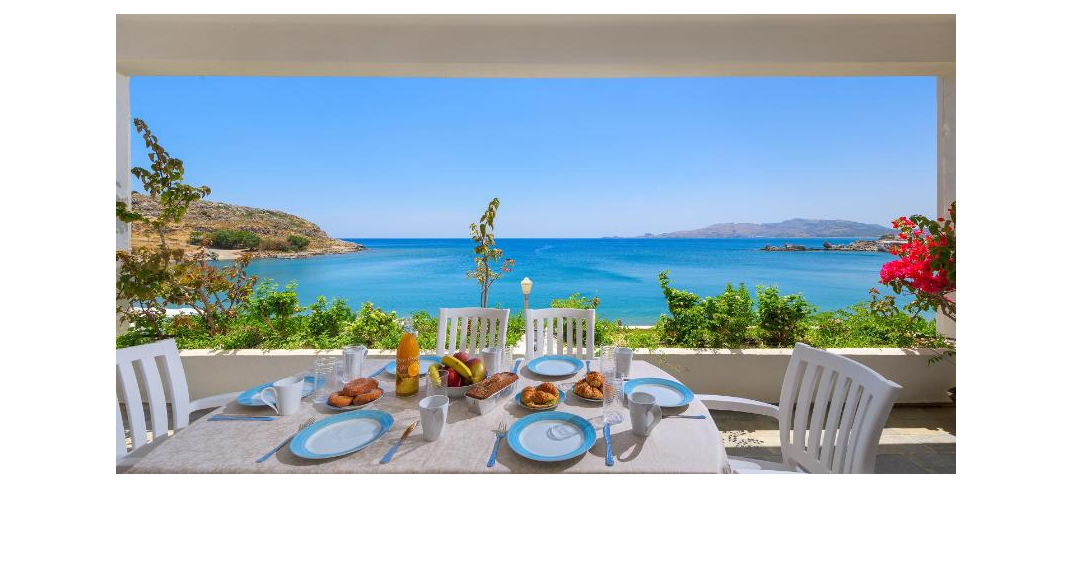

clf;clear;

img = imread("../images/sea_house.jpg");
imshow(img, [])

image = SLIC(img, 500, 0.5, 40);

Error is: 3376.7879
Error is: 90.4248
Error is: 24.7998
Error is: 11.7977
Error is: 5.9181
Error is: 3.4432
Error is: 1.8004
Error is: 1.2447
Error is: 0.76668
Error is: 0.46572


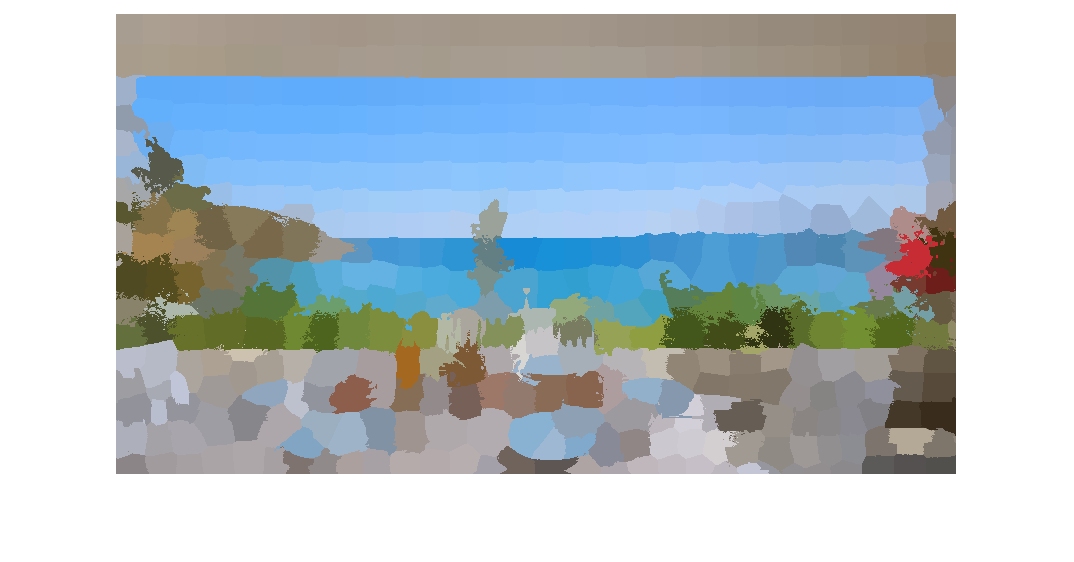

imshow(image, [])

function image = SLIC(img, K, Threshold, m)
    [M, N, ~] = size(img);
    lab_img = rgb2lab(img);
    S = int32(sqrt(M * N / K));
    pad_x = S - mod(M, S);
    pad_y = S - mod(N, S);
    pad_img = padarray(lab_img, [double(pad_x), double(pad_y)], "symmetric", "post");
    [P, Q, C] = size(pad_img);
    [Y, X] = meshgrid(1:Q, 1:P);
    data = cat(3, pad_img, X, Y);
    g_x = imfilter(rgb2gray(lab2rgb(pad_img)), [-1, 1]');
    g_y = imfilter(rgb2gray(lab2rgb(pad_img)), [-1, 1]);
    G = sqrt(g_x.^2 + g_y.^2);
    clusters = zeros([round(P/S)*round(Q/S), 5]);
    idx = 1;
    for i=0:(round(P/S)-1)
        for j=0:(round(Q/S)-1)
            x = i * S + S/2;
            y = j * S + S/2;
            window = G((x-1):(x+1), (y-1):(y+1));
            [r, c] = find(window == min(window(:)));
            x = x-(2-r(1));
            y = y-(2-c(1));
            clusters(idx, 1:3) = pad_img(x, y);
            clusters(idx, 4:5) = [x, y];
            idx = idx + 1;
        end
    end
    E = 1e8;
    labels = zeros([P, Q]) - 1;
    Distences = zeros([P, Q]) + 1e8;
    while E > Threshold
        for k=1:length(clusters)
            Center = clusters(k, :);
            lab = Center(1:3)';
            C_x = Center(4);
            C_y = Center(5);
            for i=-S:(S-1)
                x = C_x + i;
                if x < 1 || x > P
                    continue
                end
                for j=-S:(S-1)
                    y = C_y + j;
                    if y < 1 || y > Q
                        continue
                    end
                    d_c = norm(squeeze(pad_img(x, y, :)) - lab, 2);
                    d_s = norm(double([x, y]) - [C_x, C_y], 2);
                    D = sqrt(d_c^2 + (d_s/double(S))^2*m^2);
                    if D < Distences(x, y)
                        Distences(x, y) = D;
                        labels(x, y) = k;
                    end
                end
            end
        end
        new_clusters = zeros([round(P/S)*round(Q/S), 5]);
        count = zeros([round(P/S)*round(Q/S), 1]);
        for x=1:P
            for y=1:Q
                new_clusters(int32(labels(x, y)), :) = new_clusters(int32(labels(x, y)), :) + squeeze(data(x, y, :))';
                count(int32(labels(x, y))) = count(int32(labels(x, y))) + 1;
            end
        end
        new_clusters = new_clusters ./ (count+1e-8);
        E = norm(new_clusters - clusters, 2);
        clusters = new_clusters;
        disp(['Error is: ' num2str(E)])
    end
    image = zeros([P, Q, C]);
    for x=1:P
        for y=1:Q
            center = clusters(int32(labels(x, y)), :);
            image(x, y, :) = center(1:3);
        end
    end
    image = lab2rgb(image(1:M, 1:N, :));
end